x_in = load('ConcValues/runMulti/x_in_19e-1fM_multi32_600_75_runs100.mat').x_in;
C_O_all = load('ConcValues/runMulti/C_O_all_19e-1fM_multi32_600_75_runs100.mat').C_O_all;

bitSize = size(x_in,2);
nRuns = size(x_in,1);
Dt = 0.1;
inDur = 600;
sampSize = 2*inDur/Dt;


% figure()
% 
% for j = 1:bitSize
%     strt = (sampSize*(j-1)) + 1;
%     stp = sampSize*j;
%     plot(C_O_all((strt:stp),1));
%     hold on;
% end
% hold off;

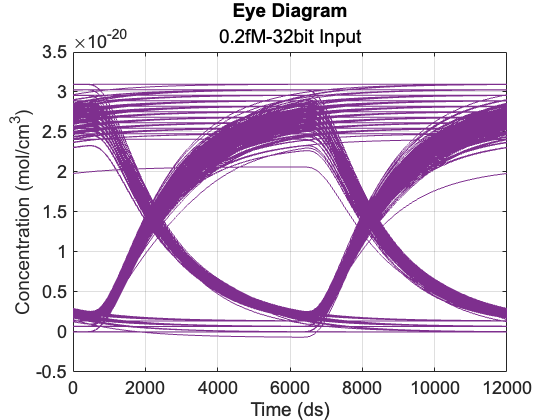

figure()
for i = 1:nRuns
    for j = 1:1:bitSize/2
        strt = (sampSize*(j-1)) + 1;
        stp = sampSize*j;
        plot(C_O_all((strt:stp),i),LineWidth=0.1,Color=[0.4940 0.1840 0.5560]);
        hold on;
    end
end
hold off;
grid on;
set(gca,'FontSize',18); set(gca,'FontName','Arial');
xlabel('Time (ds)'), ylabel('Concentration (mol/cm^{3})');
title('Eye Diagram','0.2fM-32bit Input');
% print ('Eye19e-1_32_600_75_full','-depsc');
% print ('Eye19e-1_32_600_75_full','-dpdf');
% print ('Eye19e-1_32_600_75_full','-dmeta');
print ('Eye19e-1_32_600_75_fullPurple','-dsvg');